# Campo eléctrico de cargas puntuales

### Caso 2D (una carga)

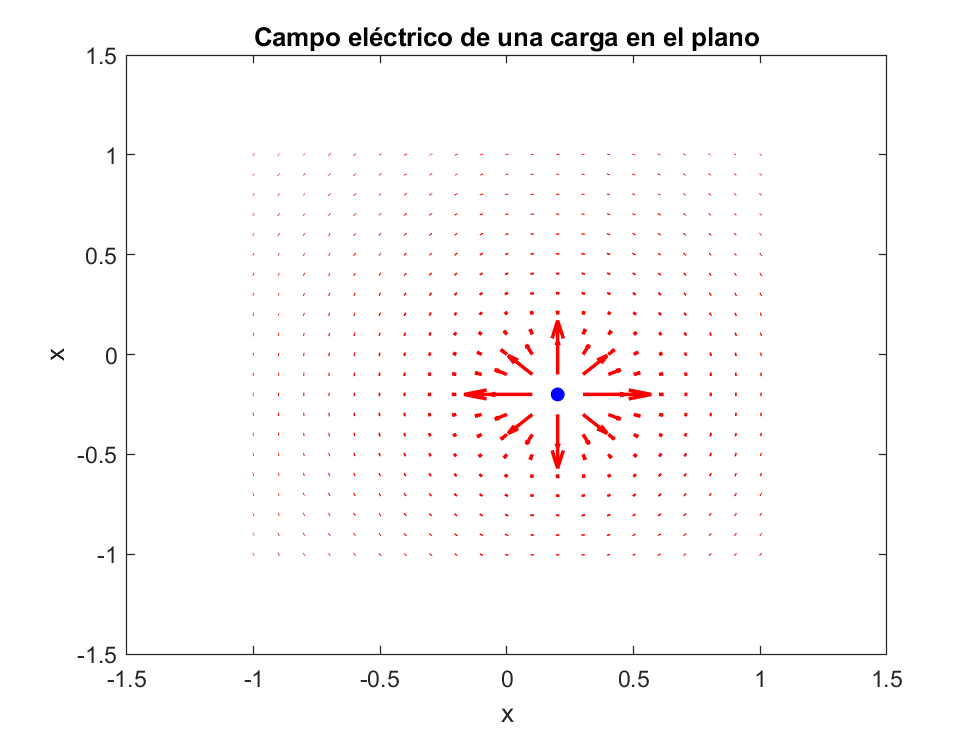

% Propiedades de la carga
q = 1e-6;       
xq = 0.2;
yq = -0.2;

% Posiciones donde vamos a evaluar el campo eléctrico
xl = linspace(-1, 1, 21);
yl = linspace(-1, 1, 21);
[x, y] = meshgrid(xl, yl);

% Calcula campo eléctrico
[Ex, Ey] = electric_field(q, xq, yq, x, y);
quiver(x, y, Ex, Ey, 2, 'linewidth', 1.5, 'color', 'r')
xlabel('x')
ylabel('y')
title('Campo eléctrico de una carga en el plano')

% Agrega la carga en el plano
hold on
scatter(xq, yq, 'b', 'filled', 'LineWidth',2)
hold off

En ocasiones, sólo se desea la dirección del campo eléctrico, por lo que es necesario dividir entre su magnitud.

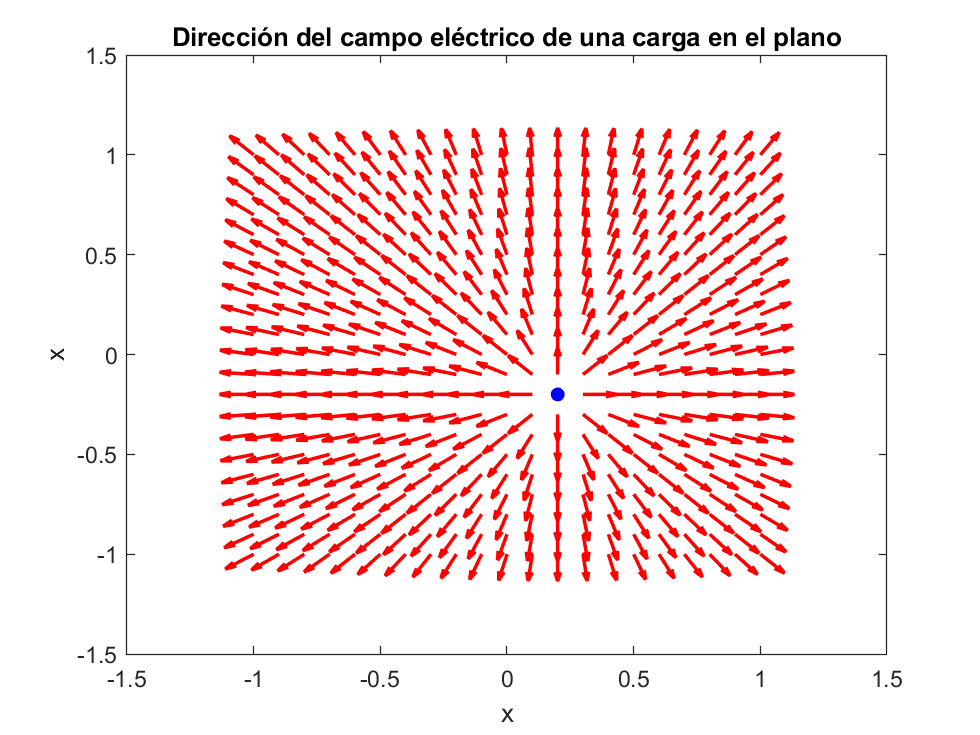

E = sqrt(Ex.^2 + Ey.^2);
quiver(x, y, Ex./E, Ey./E, 1, 'linewidth', 1.5, 'color', 'r')
xlabel('x')
ylabel('y')
title('Dirección del campo eléctrico de una carga en el plano')

hold on
scatter(xq, yq, 'b', 'filled', 'LineWidth',2)
hold off

### Caso 2D (dos cargas)

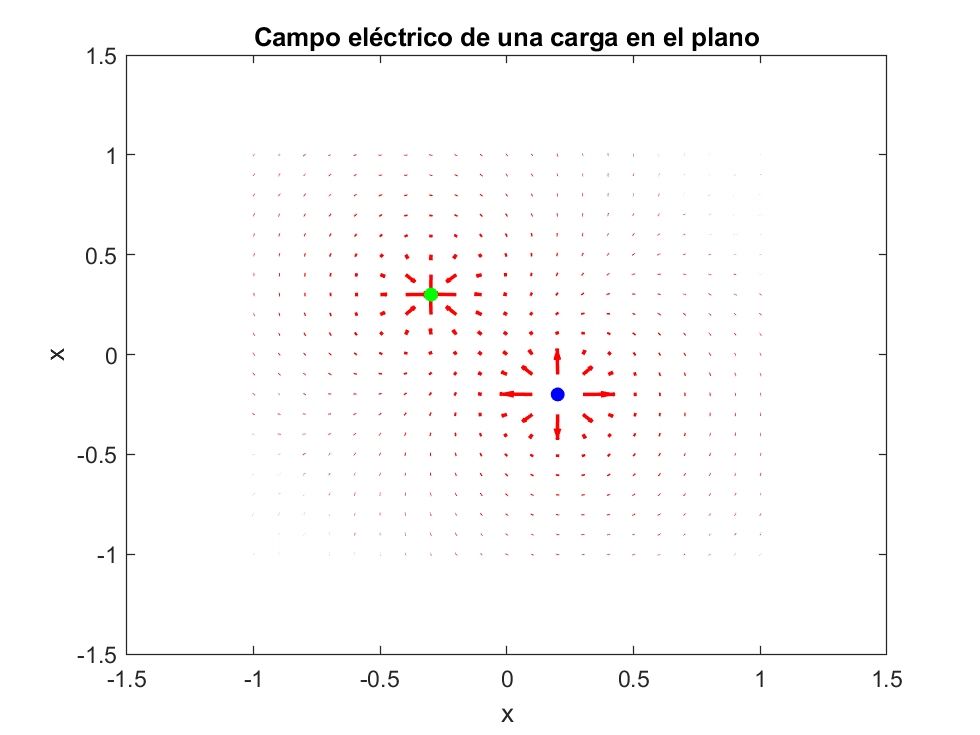

% Propiedades de la carga 1
q1 = 1e-6;       
xq1 = 0.2;
yq1 = -0.2;

% Propiedades de la carga 2
q2 = -1e-6;       
xq2 = -0.3;
yq2 = 0.3;

% Posiciones donde vamos a evaluar el campo eléctrico
xl = linspace(-1, 1, 21);
yl = linspace(-1, 1, 21);
[x, y] = meshgrid(xl, yl);

[Ex1, Ey1] = electric_field(q1, xq1, yq1, x, y);
[Ex2, Ey2] = electric_field(q2, xq2, yq2, x, y);
Ex = Ex1 + Ex2;
Ey = Ey1 + Ey2;

quiver(x, y, Ex, Ey, 0.8, 'linewidth', 1.5, 'color', 'r')
xlabel('x')
ylabel('y')
title('Campo eléctrico de una carga en el plano')

hold on
scatter(xq1, yq1, 'b', 'filled', 'LineWidth',2)
scatter(xq2, yq2, 'g', 'filled', 'LineWidth',2)
hold off

En este caso, también podría ser mejor calcular sólo la dirección del campo.

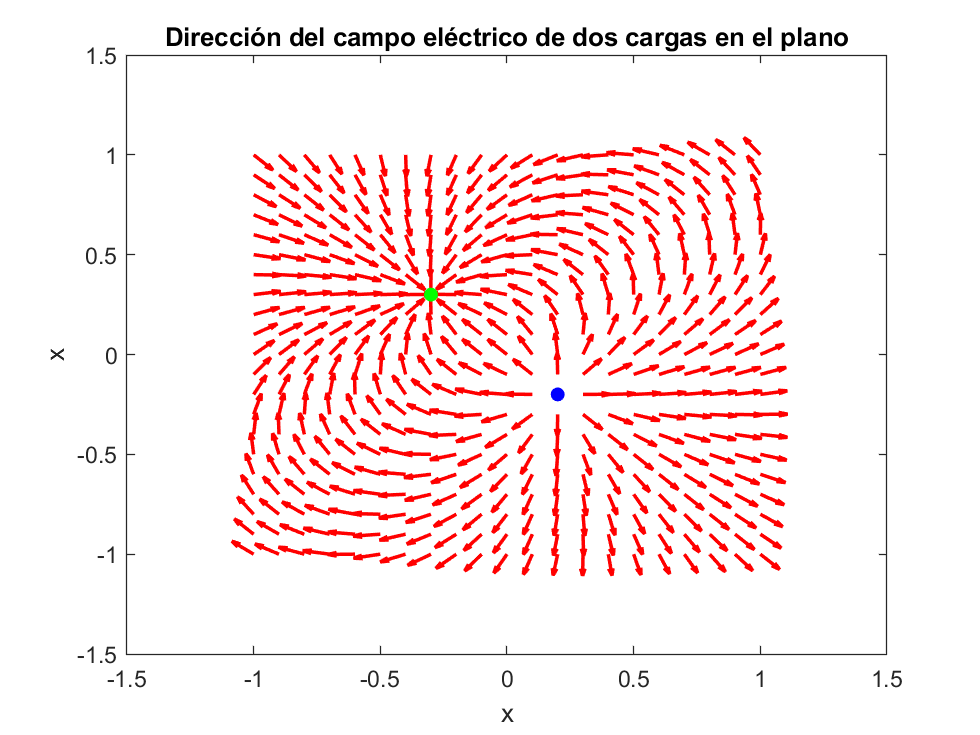

E = sqrt(Ex.^2 + Ey.^2);
quiver(x, y, Ex./E, Ey./E, 0.8, 'linewidth', 1.5, 'color', 'r')
xlabel('x')
ylabel('y')
title('Dirección del campo eléctrico de dos cargas en el plano')
hold on
scatter(xq1, yq1, 'b', 'filled', 'LineWidth',2)
scatter(xq2, yq2, 'g', 'filled', 'LineWidth',2)
hold off

### Caso 3D (una carga)

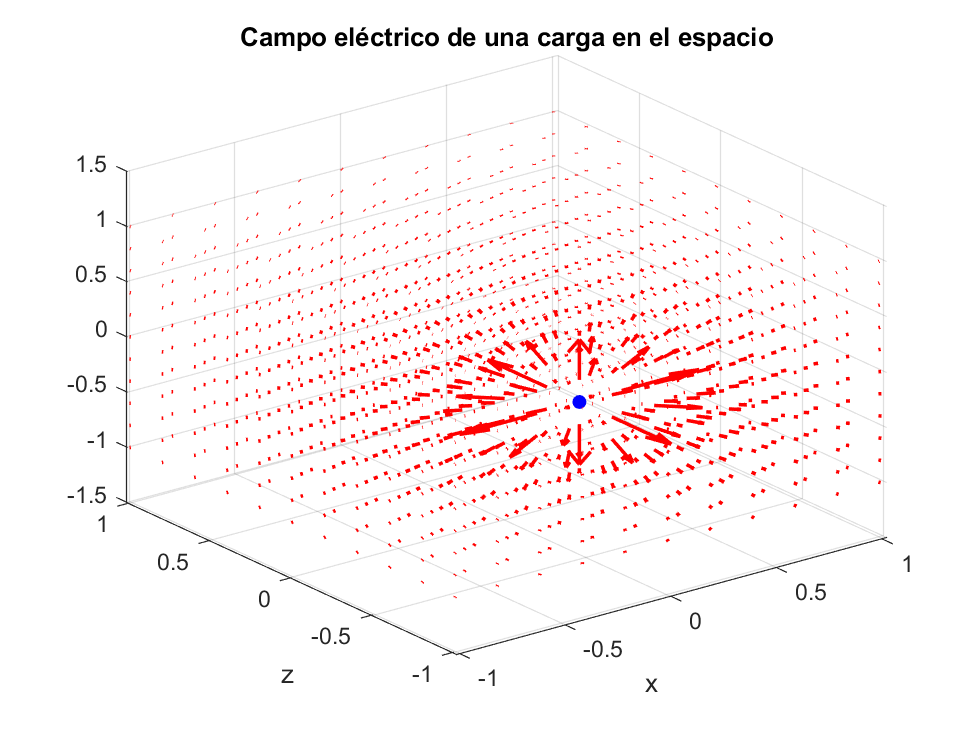

% Propiedades de la carga
q = 1e-6;       
xq = 0.2;
yq = -0.2;
zq = -0.4;

% Posiciones donde vamos a evaluar el campo eléctrico
xl = linspace(-1, 1, 11);
yl = linspace(-1, 1, 11);
zl = linspace(-1, 1, 11);
[x, y, z] = meshgrid(xl, yl, zl);

% Calcula campo eléctrico
[Ex, Ey, Ez] = electric_field3(q, xq, yq, zq, x, y, z);
quiver3(x, y, z, Ex, Ey, Ez, 2, 'linewidth', 1.5, 'color', 'r')
xlabel('x')
ylabel('y')
ylabel('z')
title('Campo eléctrico de una carga en el espacio')

% Agrega la carga en el plano
hold on
scatter3(xq, yq, zq, 'b', 'filled', 'LineWidth',2)
hold off

En ocasiones, sólo se desea la dirección del campo eléctrico, por lo que es necesario dividir entre su magnitud.

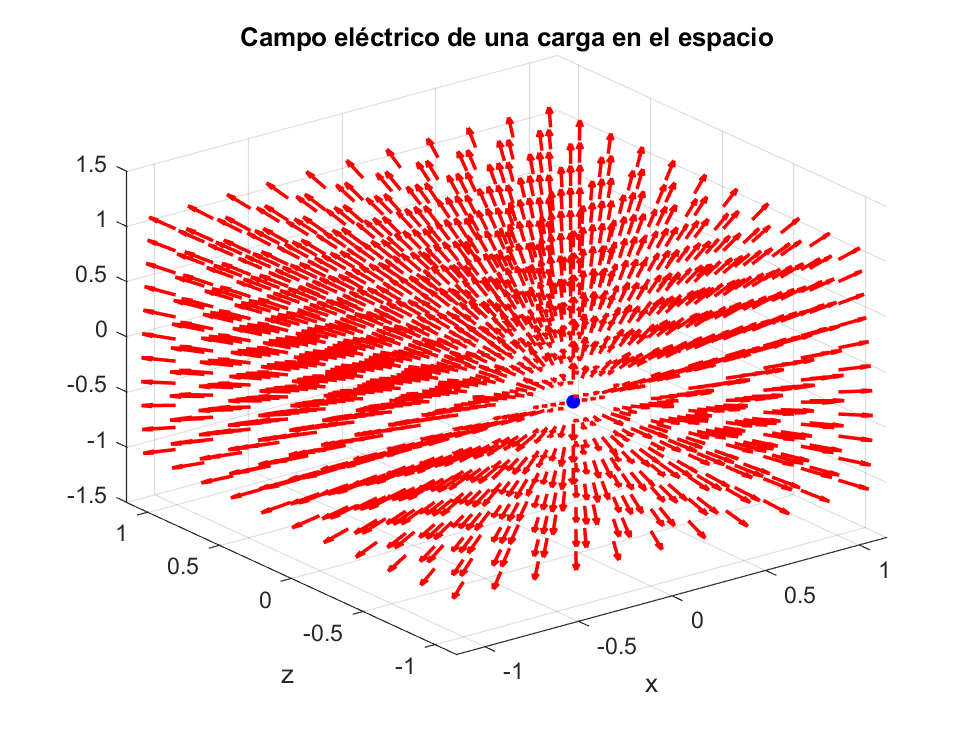

E = sqrt(Ex.^2 + Ey.^2 + Ez.^2);
quiver3(x, y, z, Ex./E, Ey./E, Ez./E, 0.8, 'linewidth', 1.5, 'color', 'r')
xlabel('x')
ylabel('y')
ylabel('z')
title('Campo eléctrico de una carga en el espacio')

hold on
scatter3(xq, yq, zq, 'b', 'filled', 'LineWidth',2)
hold off

## Función para campo eléctrico en 2D

function [Ex, Ey] = electric_field(q, xq, yq, x, y)
% Calcula el campo eléctrico en los puntos x, y debido a una carga puntual 
% localizada en (xq, yq) . Regresa los valores de las componentes Ex Ey
% del campo.

% Verifica que los parámetros de entrada sean válidos
if nargin ~= 5
    error('Cantidad de parámetros de entrada no válido.')
end

if ~isscalar(q) || ~isnumeric(q)
    error('El valor de la carga debe ser numérico y escalar.')
end

if ~isscalar(xq) || ~isnumeric(xq)
    error('El valor de xq debe ser numérico y escalar.')
end

if ~isscalar(yq) || ~isnumeric(yq)
    error('El valor de yq debe ser numérico y escalar.')
end

if ~isnumeric(x)
    error('x debe ser una matriz numérica.')
end

if ~isnumeric(y)
    error('y debe ser una matriz numérica.')
end

if size(x) ~= size(y)
    error('Las matrices x, y deben de ser del mismo tamaño.')
end

% Calcula el campo eléctrico
k = 1/(4*pi*8.8541878176e-12);
rx = x - xq;
ry = y - yq;
r = sqrt(rx.^2 + ry.^2);

Ex = k*q*rx./(r.^3);
Ey = k*q*ry./(r.^3);

end

## Función para campo eléctrico en 3D

function [Ex, Ey, Ez] = electric_field3(q, xq, yq, zq, x, y, z)
% Calcula el campo eléctrico en los puntos x, y, x debido a una carga puntual 
% localizada en (xq, yq, zq) . Regresa los valores de las componentes Ex Ey
% Ez
% del campo.

% Calcula el campo eléctrico
k = 1/(4*pi*8.8541878176e-12);
rx = x - xq;
ry = y - yq;
rz = z - zq;
r = sqrt(rx.^2 + ry.^2 + rz.^2);

Ex = k*q*rx./(r.^3);
Ey = k*q*ry./(r.^3);
Ez = k*q*rz./(r.^3);

end